# Mobile robot modeling

vx and vy are assumed to be decoupled for simplicity of the first controller implementation. The goal is to find the a first order representation of the dynamics of the system. It is worth noting that data was obtained through experiments.

Important to note that velocities are done in local frame 

clear all
close all
T = 0.5; % time constant
gain = 1;

## Vx

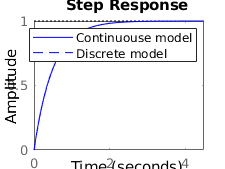

x = 0

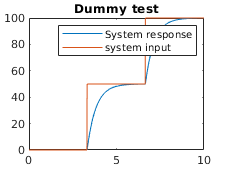

d_sysx =
 
  A = 
           x1
   x1  0.9802
 
  B = 
             u1
   x1  0.009901
 
  C = 
       x1
   y1   2
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



dt = 0.01; % sampling time

d_sysx = obtain_discrete_model_fisrt_order(T,gain, true, dt)

## vy

x = 0

d_sysy =
 
  A = 
           x1
   x1  0.9802
 
  B = 
             u1
   x1  0.009901
 
  C = 
       x1
   y1   2
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.





d_sysy = obtain_discrete_model_fisrt_order(T, gain, true, dt)


save ./models/ugv/ugv_model.mat d_sysx d_sysy